# Plots the network topology.

This example contains: Load a network. Plot network topology. Plot node IDs. Plot links IDs. Plot link indices. Plot node indices. Highlight specific links. Highlight specific nodes. Plot only links. Plot only nodes. Highlight multiple links with different colors. Highlight multiple nodes with different colors. Hide legend. Extent network on figure. Legend Position. Plot at specific axes. Plot for matlab apps (GUIs). Plot colors. Unload library.

Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


 Load a network

d = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.003}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded sucessfuly.


 Plot network topology

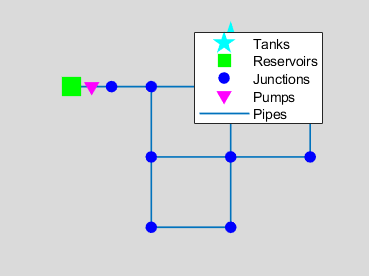

d.plot;

 Plot nodes IDs

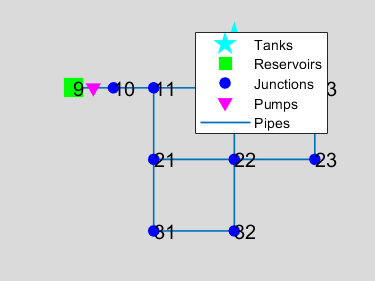

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot('nodes', 'yes', 'fontsize', 12)

Plot links IDs

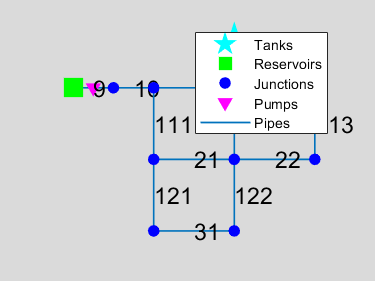

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot('links', 'yes', 'fontsize', 14)

 Plot link indices

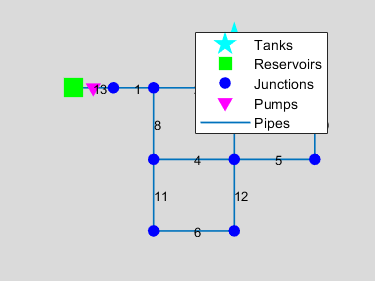

d.plot('linksindex', 'yes', 'fontsize',8);

 Plot node indices

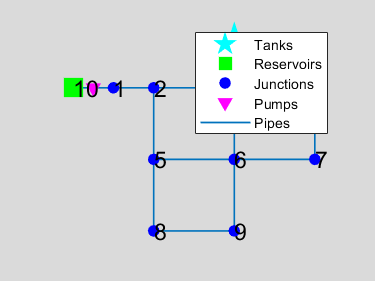

d.plot('nodesindex', 'yes', 'fontsize',14);

Highlight specific links

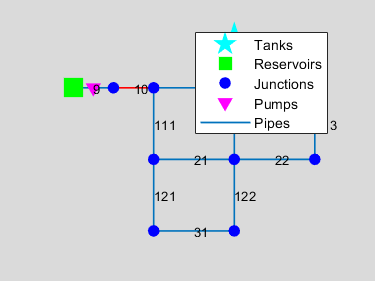

d.plot('links', 'yes', 'highlightlink',{'10'}, 'fontsize',8);        

 Highlight specific nodes

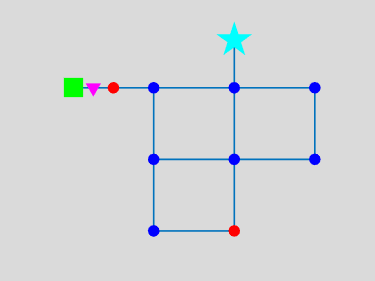

d.plot('highlightnode',{'10', '32'});

 Plot only links

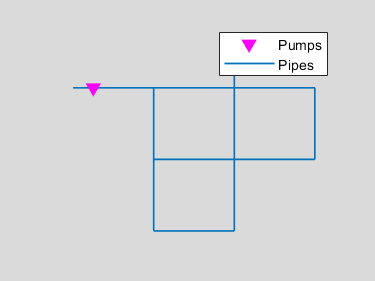

d.plot('point', 'no');

 Plot only nodes

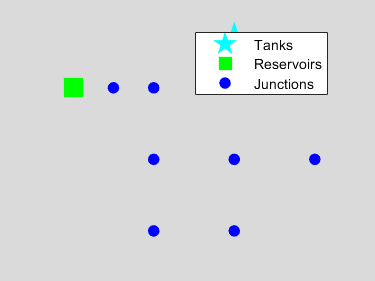

d.plot('line', 'no');

 Highlight multiple links with different colors 

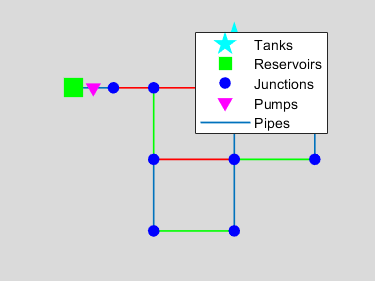

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


linkSet1 = d.getLinkNameID(1:4);
colorLinkSet1 = repmat({'r'},1,length(linkSet1));
linkSet2 = d.getLinkNameID([5,6,7,8]);
colorLinkSet2=repmat({'g'},1,length(linkSet2));
d.plot('highlightlink',[linkSet1 linkSet2],'colorlink',[colorLinkSet1 colorLinkSet2])

 Highlight multiple nodes with different colors 

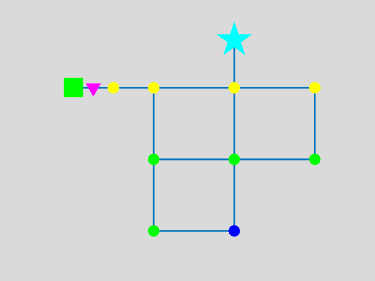

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


nodeSet1 = d.getNodeNameID(1:4);
colorLinkSet1 = repmat({'y'},1,length(nodeSet1));
nodeSet2 = d.getNodeNameID([5,6,7,8]);
colorLinkSet2=repmat({'g'},1,length(nodeSet2));
d.plot('highlightnode',[nodeSet1 nodeSet2],'colornode',[colorLinkSet1 colorLinkSet2])

 Hide legend

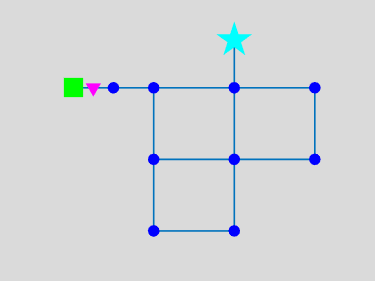

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot('legend', 'hide')

 Extent network on figure

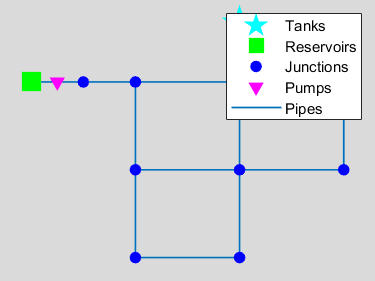

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0 0 1 1]
            Units: 'normalized'

  Show all properties


d.plot('extend', 'yes')

 Legend Position

       'North'              inside plot box near top

       'South'              inside bottom

       'East'               inside right

       'West'               inside left

       'NorthEast'          inside top right (default for 2-D plots)

       'NorthWest'          inside top left

       'SouthEast'          inside bottom right

       'SouthWest'          inside bottom left

       'NorthOutside'       outside plot box near top

       'SouthOutside'       outside bottom

       'EastOutside'        outside right

       'WestOutside'        outside left

       'NorthEastOutside'   outside top right (default for 3-D plots)createP

       'NorthWestOutside'   outside top left

       'SouthEastOutside'   outside bottom right

       'SouthWestOutside'   outside bottom left

       'Best'               least conflict with data in plot

       'BestOutside'        least unused space outside plot

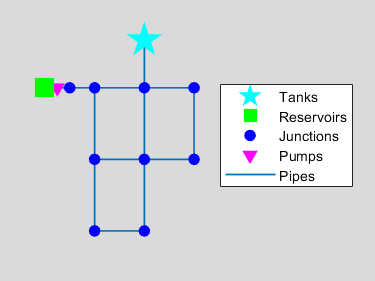

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1023 0.1100 0.6099 0.8150]
            Units: 'normalized'

  Show all properties


d.plot('legendposition', 'EastOutside')

 Plot at specific axes

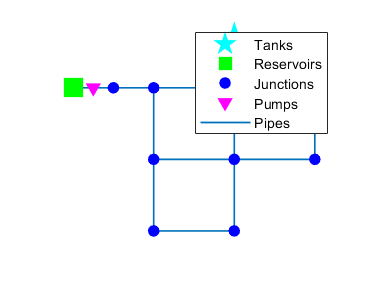

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


h = figure;
d.plot('axes', h)


% Plot for matlab apps (GUIs)
%d.plot('uifigure', app.UIFigure, 'axes', app.UIAxes,'legend','hide');

 Unload library

d.unload

EPANET Class is unloaded
